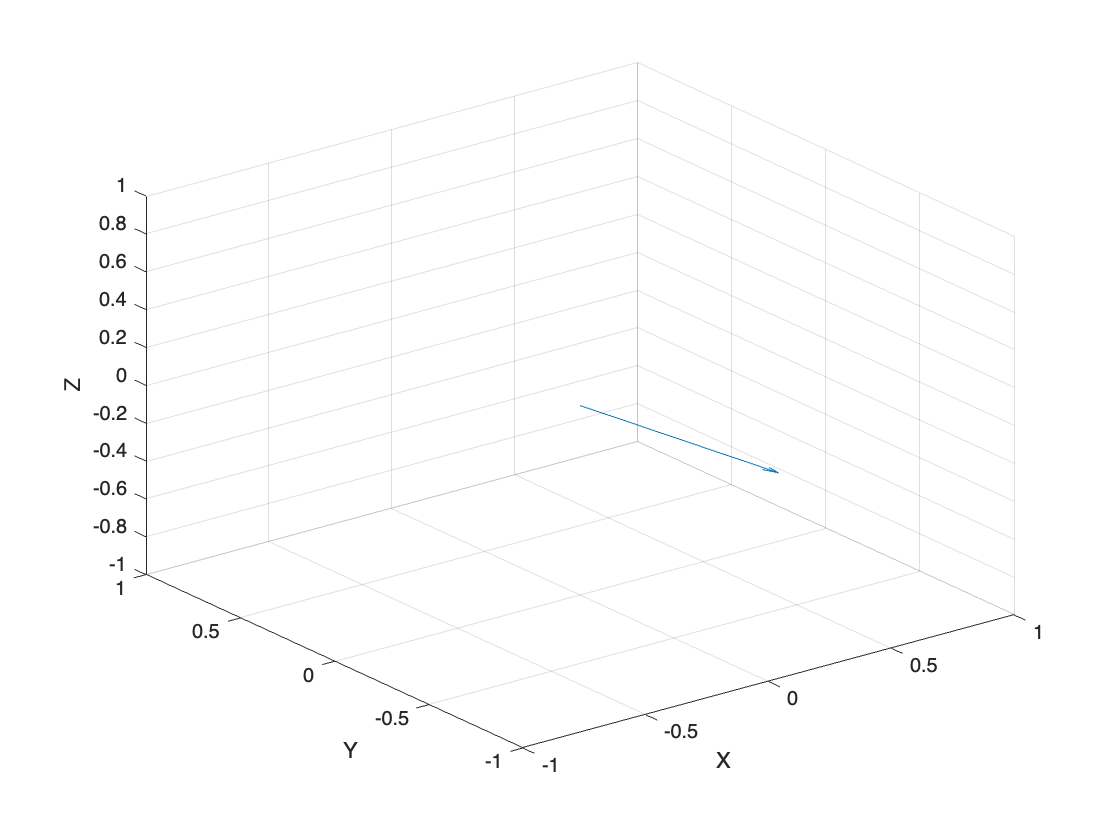

pt = [0 0 0];
dir = [1 0 0 1];
h = quiver3(pt(1),pt(2),pt(3), dir(1),dir(2),dir(3));
xlim([-1 1])
ylim([-1 1])
zlim([-1 1])


data = csvread('FA_16_40_00_00_07_06_00 (1).csv', 1, 0);
roll = data(1:100:end, 3);
pitch = data(1:100:end, 2);
yaw = data(1:100:end, 1);

if length(roll) ~= length(pitch) || length(pitch) ~= length(yaw)
    error('Arrays are not the same length');
end

for i = 1:length(roll)
    xfm = makehgtform('xrotate', roll(i)*(pi/180), 'yrotate', ...
        pitch(i)*(pi/180), 'zrotate', yaw(i)*(pi/180)); 
        % create transformation matrix
    
    newdir = xfm * dir'; % transform the arrow direction
    
    h.UData = newdir(1);
    h.VData = newdir(2);
    h.WData = newdir(3);

    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    
    drawnow % update the plot
    pause(0.05) % add a 0.05 second pause
end
